# Second-Order Linear DEs in MATLAB

## Iode for Second-Order Linear DEs with constant coefficients

## Exercise 1

Objective: Use `iode` to solve second-order linear DEs. And classify them.

Details: Consider the ODE:

(a) Use `iode` to plot six (6) numerical solutions of this equation with "random" initial data (use Method 3 above) and press-and-drag at various initial points, with some of the slopes being positive and some negative)

Use only initial points in the part of the window where `0<t<1` and `-1<x<1` and take all initial slopes between `-3` and `+3`.

Change the window to `[0,10]x[-3,3]`. Save a cropped screenshot.

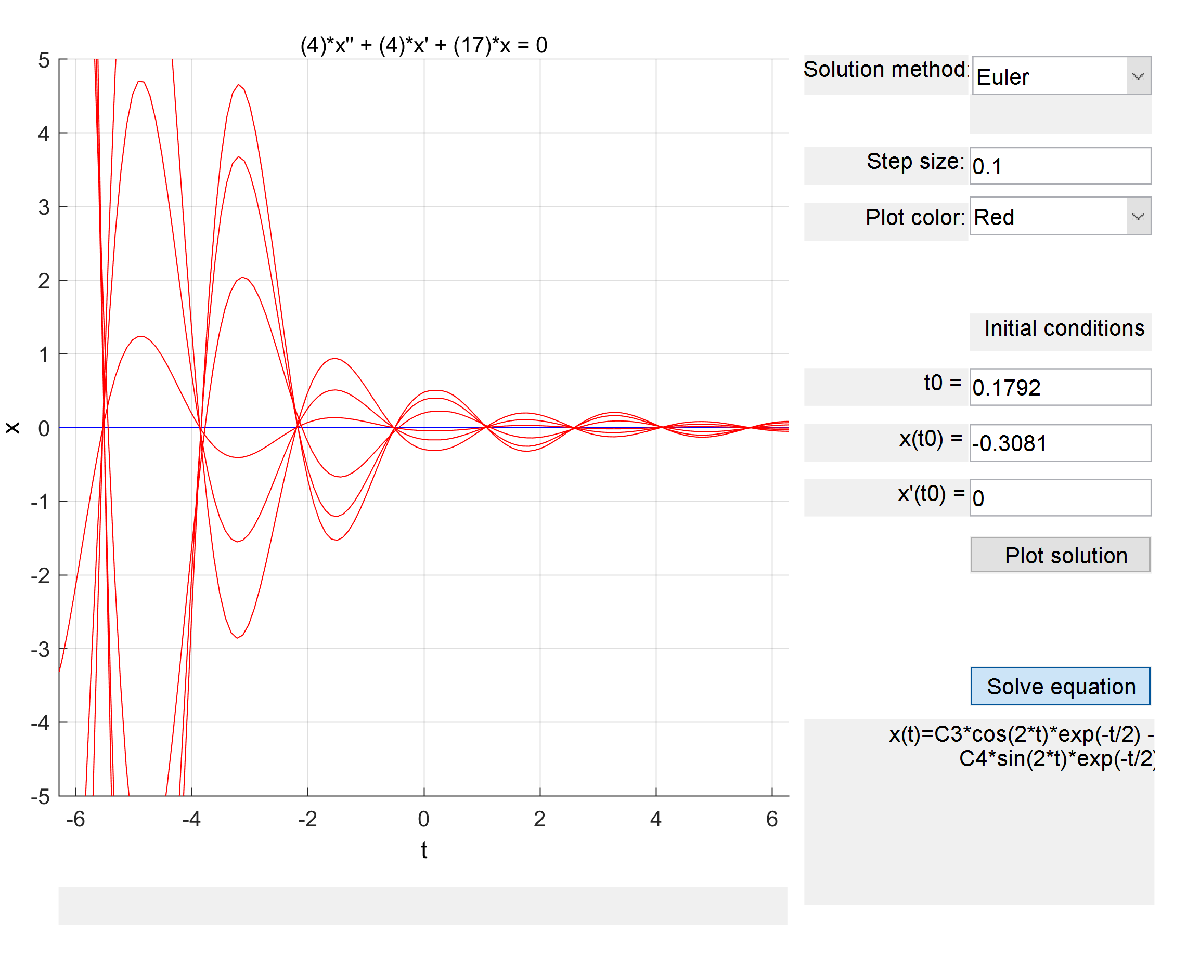

(b) Based on the results of (a), state what percentage of solutions decay, grow, grow while oscillating, or decay while oscillating.

(c) Solve the DE and write the exact solution. Explain why this justifies your answer in (b)

% (b) 100% solutions decays while oscillating but half of them are out of phase with the 
%other half's amplitudes so peaks line up with troughs 

% (c) y(t)=c1*cos(2t)exp(-t/2)-c2sin(2t)exp(-t/2)
%This justifies my answer in b because the system has complex roots
%with negative real parts, indicating a negative int he exponential. The
%imaginary parts account for the oscillations (sin and cos).
%The two superposed
%functions are sin and cos of the same 2t, but since sin and cos are out of
%phase by pi/2, it accounts for why peaks line up with troughs

## Exercise 2

Consider the ODE:

Repeat (a), (b), (c) from Exercise 1 with this DE.

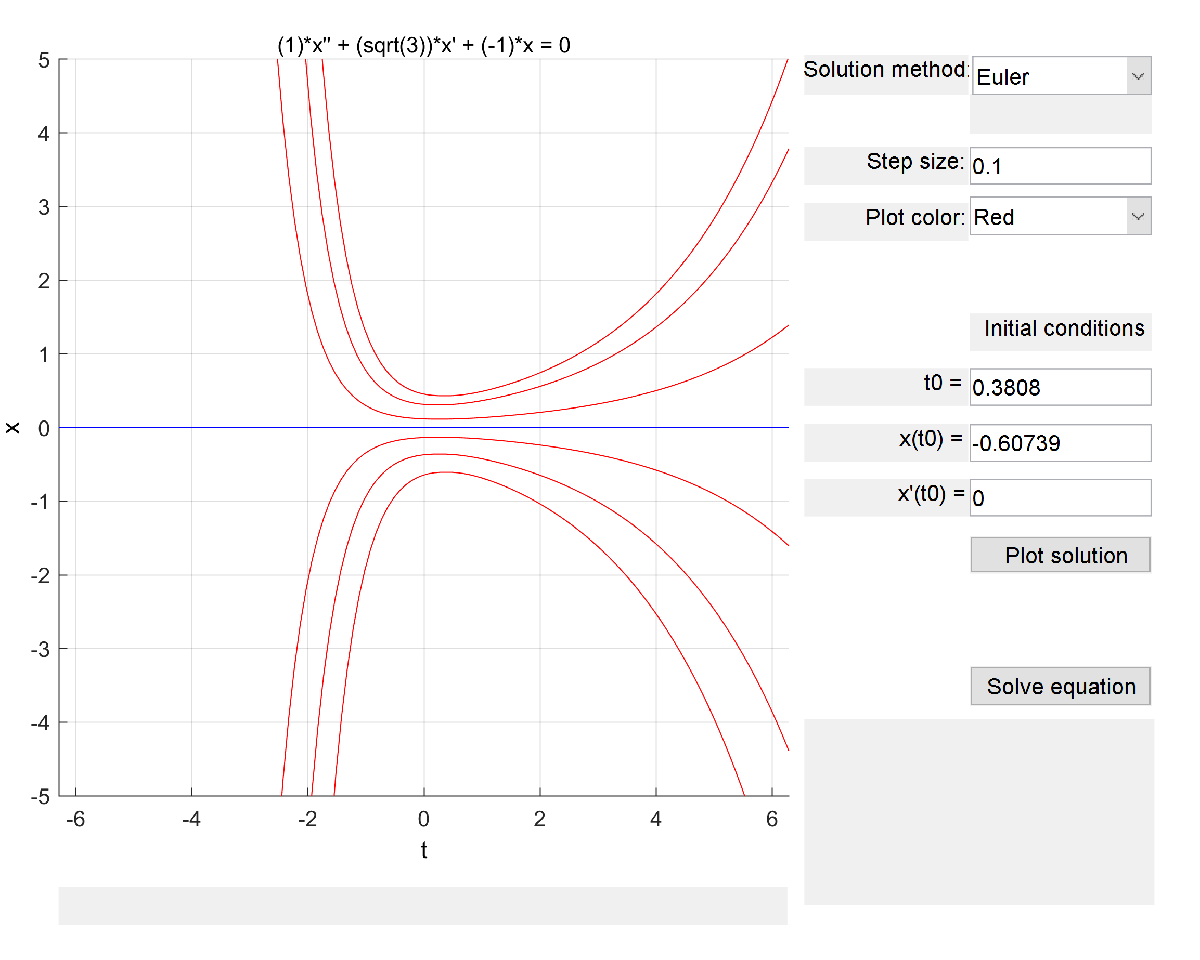

% (b) Solutions above x=0 decays initially and start growing at approximately t=0
%(50%)
% Solutions below x=0 increase initially and start decreasing at approximately t=0 
%(50%)

% (c) x(t)=c1exp(-t*(3^3(1/2)/2 +1))+ c2exp(-t*(3^(1/2)/2 -1))
%This solution makes sense because the system has distinct
%roots with opposite signs, thus one will increase and the other wil
%decrease. There are no complex roots associated with it, so no
%oscillations will occur 

## Exercise 3

Consider the ODE:

Repeat (a), (b), (c) from Exercise 1 with this DE.

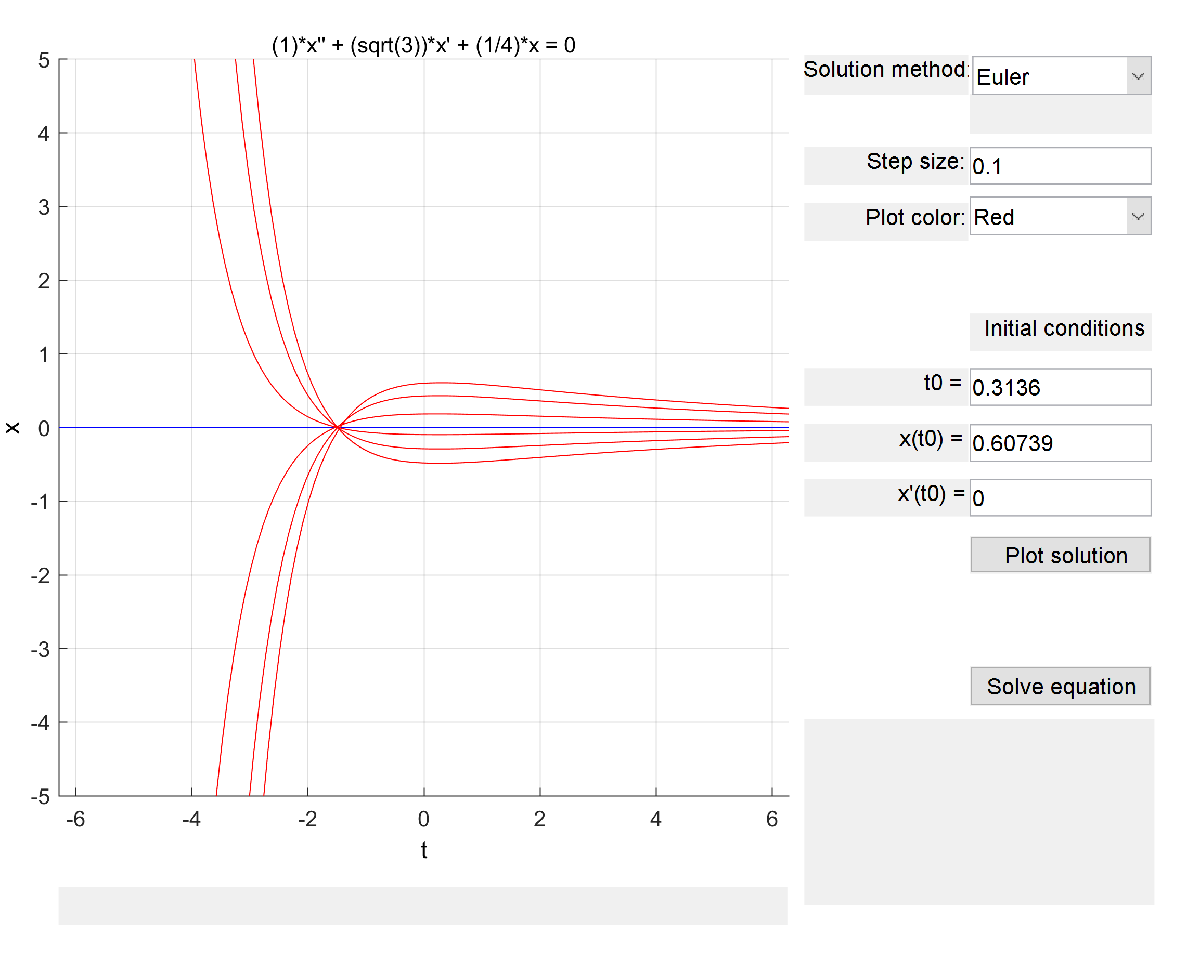

% (b) 100% of solutions decay
% (c) x(t)=c1exp(-t*(3^3(1/2)/2 +1))+ c2exp(t*(3^(1/2)/2 -1))
% This solution has real distinct roots that are both negative, making it decay over time.
% It is a stable nodal sink. 


## Example

Consider the ODE:

The solution is

From this, it is easy to see that all solutions decay while oscillating.

Similarly, for the equation 

The solution is

which grows while oscillating.

## Exercise 4

Consider the fourth-order ODE:

(a) Find the general solution for this problem. You can use MATLAB to find the roots of the characteristic equation numerically with `roots` or symbolically with `solve`.

(b) Predict what percentage of solutions with random initial data will grow, decay, grow while oscillating, and decay while oscillating. Explain.

% (a) General Solution: y = a*exp(-t)*sin(2t)+b*sin(t)+c*exp(-t)*cos(2t)+d*cos(t)

% (b) Based on the roots of the equation, which are complex with negative
% or 0 for the real part.
% Since there exists complex values, the system should ocsillate. 

% It will oscillate without without growth or
% decay if the real parts of the complex roots are zero 

% As t approaches infinity, the exponentials will approach zero, making the
% entire term containing them zero. In this case the ocsillations will
% dominate. 

% However, if b and d are 0, the solutiona will decay, due to the dominant negative roots. 

% The percentage of solutions that will decay with
% oscillation is approximately 0.01% while the percentage of solutions that will
% neither grow nor decay but will oscillate is 99.99%

## Exercise 5

Objective: Classify equations given the roots of the characteristic equation.

Details: Your answer can consist of just a short sentence, as `grows` or  `decays while oscillating`.

Consider a second-order linear constant coefficient homogeneous DE with `r1` and `r2` as roots of the characteristic equation.

Summarize your conclusions about the behaviour of solutions for randomly chosen initial data when.

(a) `0 < r1 < r2`

%Grows with no oscillation 

(b) `r1 < 0 < r2`

%Decays first BUT THEN grows with no oscillation 

(c) `r1 < r2 < 0`

% Decays with no oscillation 

(d) `r1 = alpha + beta i` and  `r2 = alpha - beta i` and `alpha < 0`

%Decays while oscillating 

(e) `r1 = alpha + beta i` and  `r2 = alpha - beta i` and `alpha = 0`

%Oscillates without growth or decay 

(f) `r1 = alpha + beta i` and  `r2 = alpha - beta i` and `alpha > 0`

%Grows while oscillating 

## Numerical Methods for Second-Order ODEs

One way to create a numerical method for second-order ODEs is to approximate derivatives with finite differences in the same way of the Euler method.

This means that we approximate the first derivative by:

and

By writing these approximations into the ODE, we obtain a method to get `y[n+1]` from the previous two steps `y[n]` and `y[n-1]`.

The method for approximating solutions is:

1. Start with `y[0]=y0`

2. Then we need to get `y[1]`, but we can't use the method, because we don't have two iterations `y[0]` and `y[-1]`(!!). So we use Euler to get

y1 is the slope given by the initial condition

3. Use the method described above to get `y[n]` for `n=2,3,...`.

## Exercise 6

Objective: Write your own second-order ODE solver.

Details: Consider the second-order ODE

Write a second-order ODE solver using the method described above.

This m-file should be a function which accepts as variables (t0,tN,y0,y1,h), where t0 and tN are the start and end points of the interval on which to solve the ODE, y0, y1 are the initial conditions of the ODE, and h is the stepsize. You may also want to pass the functions into the ODE the way `ode45` does (check MATLAB lab 2). Name the function DE2_<UTORid>.m.

Note: you will need to use a loop to do this exercise. 

%Function in separate file (DE2_wangrush.m)

## Exercise 7

Objective: Compare your method with `iode`

Details: Use `iode` to plot the solution of the ODE  `y'' + exp(-t/5) y' + (1-exp(-t/5)) y = sin(2*t)` with the initial conditions  `y(0) = 1, y'(0) = 0`

Use the window to `[0,20]x[-2,2]` Without removing the figure window, plot your solution (in a different colour), which will be plotted in the same graph. 

Comment on any major differences, or the lack thereof.

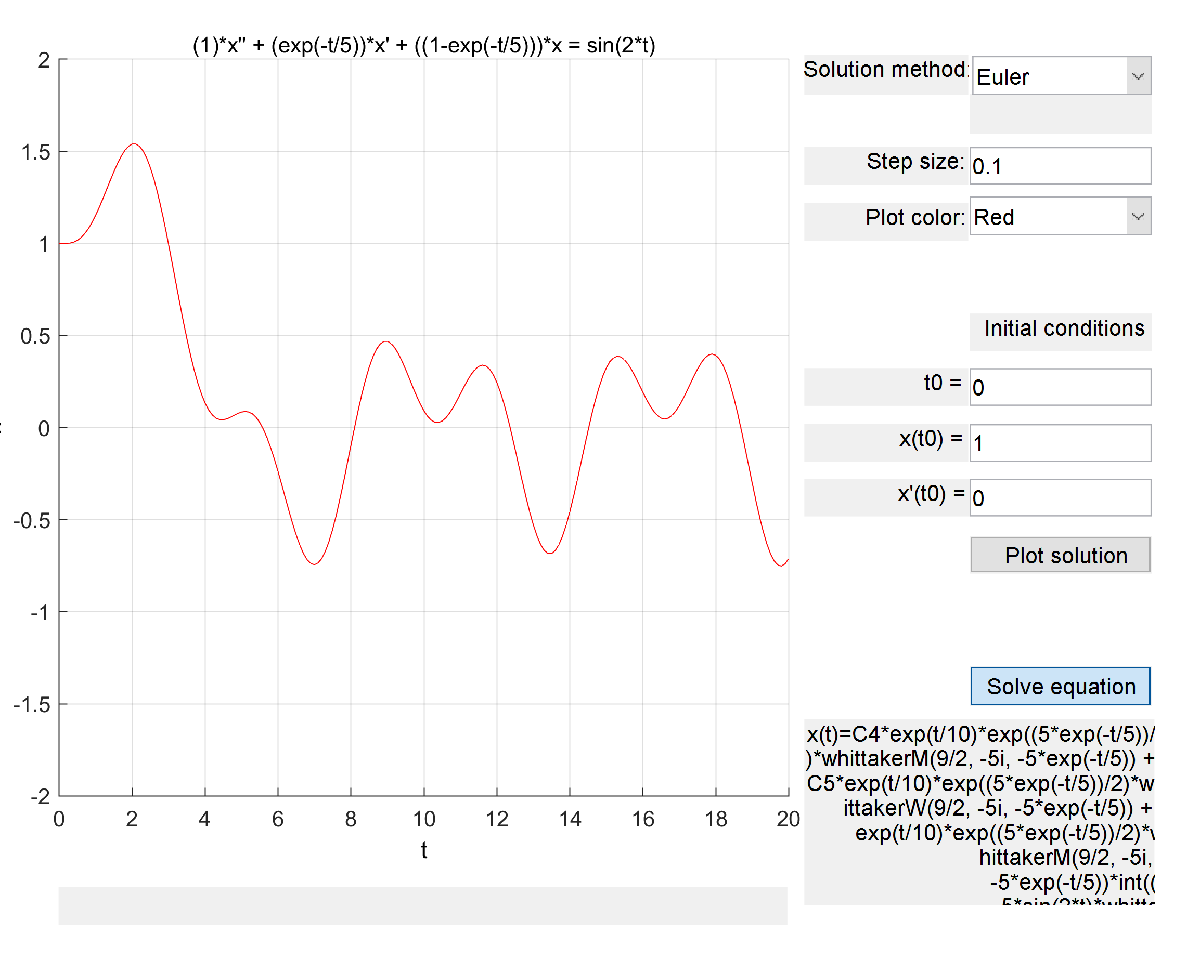

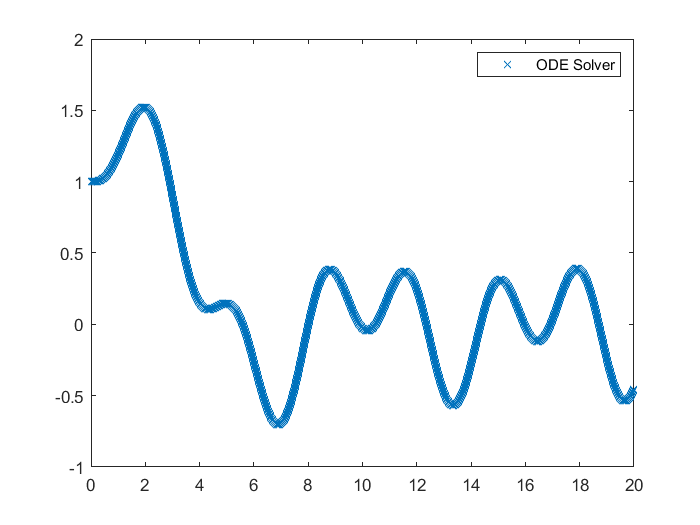

clear all;
h = 0.0005;
t0 = 0;
tN = 20;
y0 = 1;
y1 = 0;

p = @(t) exp(-t/5);
q = @(t) 1-exp(-t/5);
g = @(t) sin(2*t);

[t,y] = DE2_wangrush(t0,tN,y0,y1,h,p,q,g); %pgq are the individual functions in the overall function
plot(t,y,'x')
legend('ODE Solver')

% As time increases, the DE_2 solution appears to move further away from the actual solution 
% This is becuase the propogation of error causes error increase 
% However, both solutions follow the same oscillation pattern.
% This is expected since there is a forcing function of sin(2t). 
% The roots of the homogeneous solution are negative, so this accounts for the decay while oscillating
% over the given time period 